%% Clear temporary variables
clear variables

# Analysis of a Directional Field from a Synthetic Asymmetry Image

Description: This script loads and processes a synthetic image depicting a directional asymmetry field. The image data is extracted from an RGB format, converted to grayscale, and filled for missing values. Various statistical analyses are performed, including directional asymmetry, bivariate asymmetry, and variogram computations. The results are visualized using plots to interpret the directional properties and spatial characteristics of the image.

## Set Up Simulation Parameters

This section outlines the parameters used for simulating the random fields and computations. 

%% Load and process the PNG image
% Load the synthetic directional field image from a specified PNG file.
X = imread('E3 - SyntheticAsymmetry/Directional_field_v1.png'); 
[nx, ny, dim] = size(X); % Get dimensions of the image
x0 = grille2(1, nx, 1, 1, ny, 1); % Generate a 2D grid based on the image size
X = reshape(im2double(X(:,:,1:3)), [], 3); % Reshape and convert image data to double format


## Display the original image

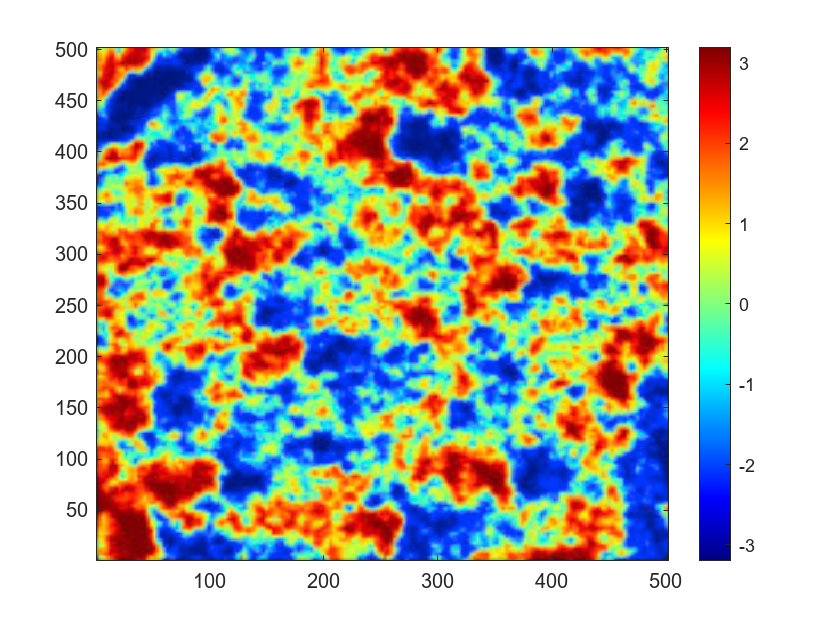

figure(1)
imagesc(reshape(X, [nx, ny, 3])); % Reshape for visualization
colorbar(); % Add a color bar to indicate value scales
colormap 'jet'; % Set colormap to 'jet' for enhanced visualization
clim([-3.2 3.2]); % Set color limits for better contrast
set(gca,'YDir','normal'); % Set Y-axis direction to normal for correct orientation

%% Prepare the image for analysis
[~, idx] = sortrows(rgb2hsv(X), -1); % Sort the RGB values based on HSV
C = gray(nx * ny); % Create a grayscale colormap
C(idx,:) = C; % Apply the sorted colormap

Im = C(:, 1); % Initialize the image
Im(Im <= 0.04) = nan; % Set low values to NaN
Im(Im >= 0.96) = nan; % Set high values to NaN
Im = reshape(Im, [nx, ny]); % Reshape for processing

% Fill missing values with nearest neighbor interpolation
filledImage = fillmissing(Im, 'nearest'); 

Z = reshape(filledImage, [nx * ny, 1]); % Reshape filled image to a vector
Z = (Z - mean(Z)) / std(Z) + rand(nx * ny, 1) / 10; % Standardize and add noise
A = reshape(Z, [nx, ny]); % Reshape back to 2D

% Apply a convolution for empirical cumulative distribution function (ECDF)
B = [1 1 1; 1 1 1; 1 1 1] / 9; % Create a smoothing kernel
Z = ECDF(reshape(conv2(A, B, "same"),[nx*ny 1])) ;


## Display the processed directional field

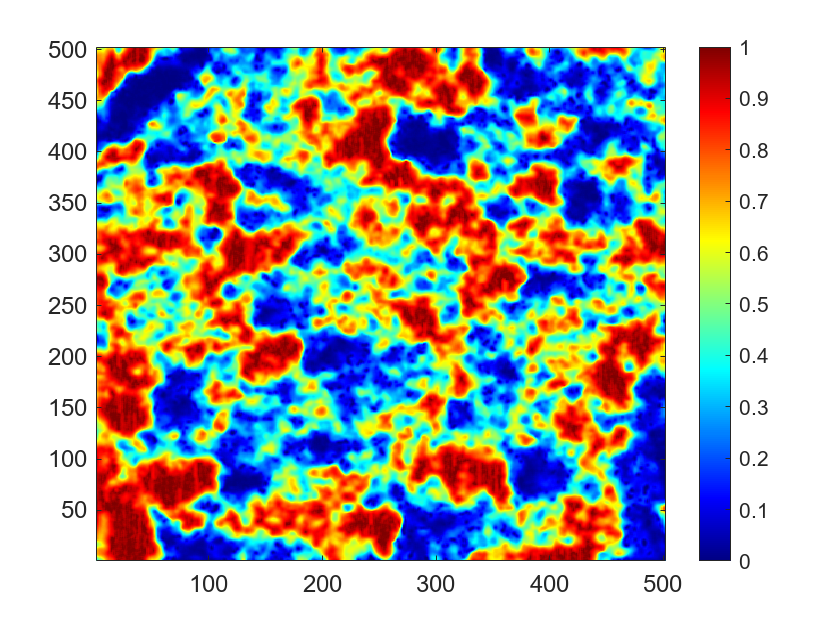

figure(2)
imagesc(reshape(Z(:,1), [nx, ny])); % Visualize the processed data
colorbar(); % Add a color bar for scaling
colormap 'jet'; % Set the colormap
clim([0 1]); % Set color limits
set(gca,'YDir','normal'); % Set Y-axis direction to normal
fontsize(gca, 12, 'points'); % Adjust font size for readability

**Compute the directional asymmetry**

This section computes the directional asymmetry of a synthetic asymmetry field. The data is classified as non-categorical by setting `categ = 0`, and visualization is enabled with `display = 1`. The field is transformed into rank values by specifying `rank = 1`, while the operation for calculating directional asymmetry is defined with `icode = 8`.

Next, 100 Gaussian random fields (GRFs) with the same variogram as the image are simulated using the `fftma` function. For each realization, the directional asymmetry is recalculated with `GeoStatFFT`, and the results are stored in `gh1`.

The results are visualized in Figure 11, where each GRF realization's asymmetry values are plotted as light gray lines. The mean asymmetry is represented by a bold black line, along with dashed lines for the 5th and 95th percentiles.

Finally, vertical and horizontal asymmetry results are displayed in green and red, respectively. The plot includes labels for the x-axis (Distance) and y-axis (Directional asymmetry value), along with a legend. Axis limits and minor ticks are adjusted to enhance readability.

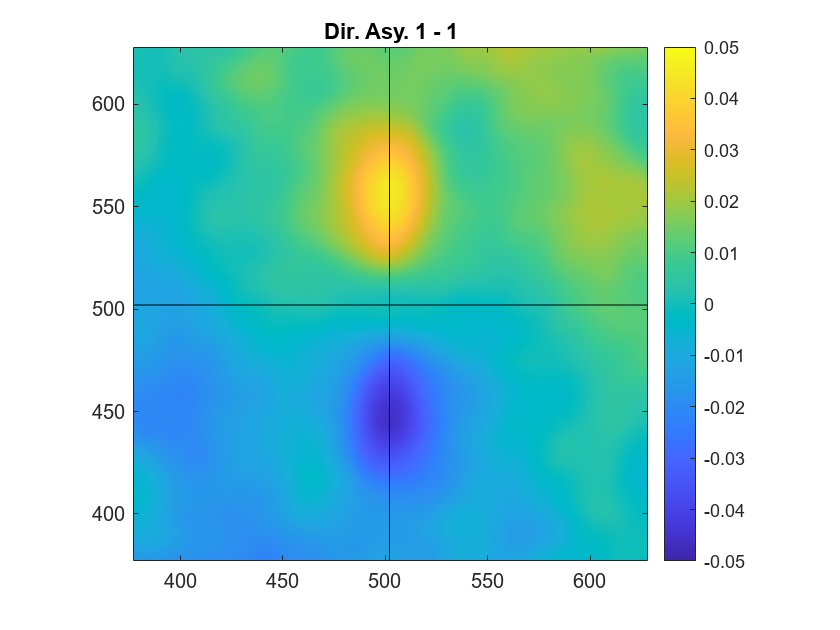

categ = 0; % Specify that the data is not categorical
display = 1; % Set display flag to true for visualization
rank = 1; % Set rank for GeoStatFFT
icode = 8; % Set code for directional asymmetry computation
figure(1000)
[gh, nh] = GeoStatFFT(x0, Z, icode, categ, display, rank); % Compute directional asymmetry

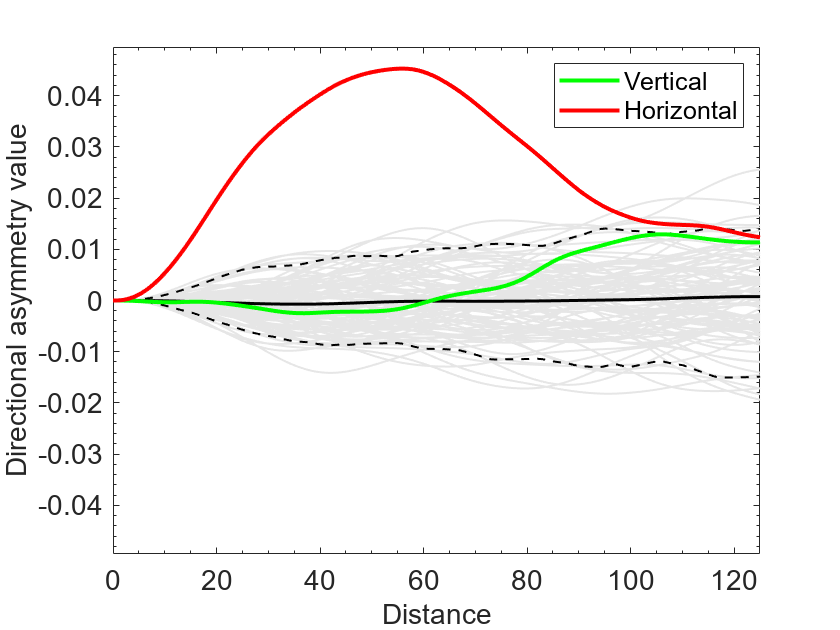

%% Simulation of random fields for directional asymmetry
[z] = fftma([6, 50, 50, 50, 0, 0, 0], 1, 45124241, 100, nx, 1, ny, 1); % Simulate random fields
for i = 1:100
    gh1{i} = GeoStatFFT(x0, z(:, i), icode, categ, 0, rank); % Compute asymmetry for each field
end

% Plot the directional asymmetry results
figure(1101)
for i = 1:100
    plot(0:length(gh1{i}{1,1}(nx:end,ny))-1, gh1{i}{1,1}(nx:end,ny), 'color', [0.9 0.9 0.9], 'LineWidth', 1) % Plot each realization
    hold on
    gmean(:, i) = gh1{i}{1,1}(nx:end, ny); % Store mean values for each realization
end
plot(0:length(mean(gmean, 2))-1, mean(gmean, 2), '-k', 'LineWidth', 1.5) % Plot mean
hold on
plot(0:length(quantile(gmean, 0.05, 2))-1, quantile(gmean, 0.05, 2), '--k', 'LineWidth', 1) % Plot 5th percentile
hold on
plot(0:length(quantile(gmean, 0.95, 2))-1, quantile(gmean, 0.95, 2), '--k', 'LineWidth', 1) % Plot 95th percentile
hold on
h1 = plot(0:length(gh{1,1}(nx:end, ny))-1, gh{1,1}(nx:end, ny), '-g', 'LineWidth', 2); % Plot vertical asymmetry
hold on
h2 = plot(0:length(gh{1,1}(nx, ny:end))-1, gh{1,1}(nx, ny:end), '-r', 'LineWidth', 2); % Plot horizontal asymmetry
legend([h1 h2], {'Vertical', 'Horizontal'}) % Add legend
xlabel('Distance') % Label x-axis
ylabel('Directional asymmetry value') % Label y-axis
fontsize(gca, 14, 'points'); % Adjust font size
xlim([0 floor(nx/4)]); % Set x-axis limits
ylim([-0.0495 0.0495]); % Set y-axis limits
set(gca,'XMinorTick','on'); % Enable minor ticks on x-axis
set(gca,'YMinorTick','on'); % Enable minor ticks on y-axis

**Compute the bivariate (or rank) asymmetry**

This section computes the bivariate (or rank) asymmetry of the synthetic asymmetry field. The data is classified as non-categorical by setting `categ = 0`, and visualization is enabled with `display = 1`. The field is transformed into rank values by specifying `rank = 1.` The operation for calculating bivariate asymmetry is specified using `icode = 9`, and the asymmetry is computed with the `GeoStatFFT` function.

Next, 100 random fields are simulated using the `fftma` function with the specified parameters. For each realization, the bivariate asymmetry is recalculated using `GeoStatFFT`, and the results are stored in `gh1`.

The results are visualized in Figure 21, where each realization's bivariate asymmetry values are plotted as light gray lines. The mean bivariate asymmetry is shown as a bold black line, along with dashed lines representing the 5th and 95th percentiles.

Vertical and horizontal bivariate asymmetry results are displayed in green and red, respectively. The plot includes labels for the x-axis (Distance) and y-axis (Rank asymmetry value). Additionally, axis limits are set to enhance readability.

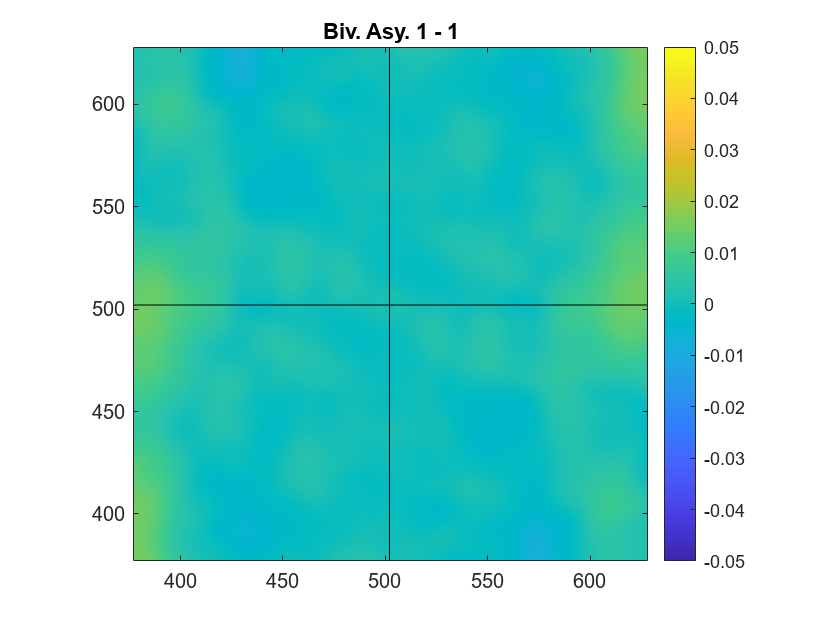

categ = 0; % Specify that the data is not categorical
display = 1; % Set display flag to true for visualization
rank = 1; % Set rank for GeoStatFFT
icode = 9; % Set code for bivariate asymmetry computation
figure(2000)
[gh, nh] = GeoStatFFT(x0, Z, icode, categ, display, rank); % Compute bivariate asymmetry

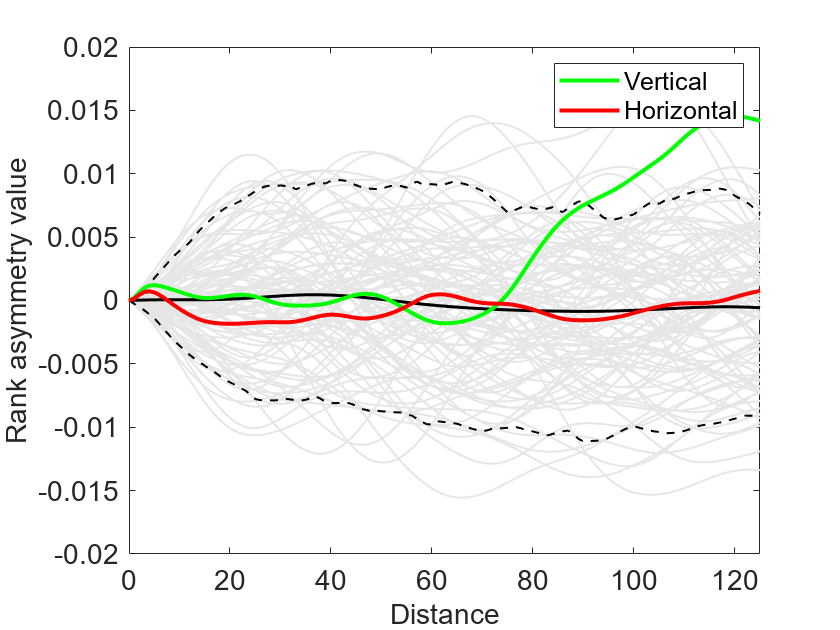

%% Simulation of random fields for bivariate asymmetry
[z] = fftma([6, 50, 50, 50, 0, 0, 0], 1, 45124241, 100, nx, 1, ny, 1); % Simulate random fields
for i = 1:100
    gh1{i} = GeoStatFFT(x0, z(:, i), icode, categ, 0, 1); % Compute asymmetry for each field
end

% Plot the bivariate asymmetry results
figure(2101)
for i = 1:100
    plot(0:length(gh1{i}{1,1}(nx:end,ny))-1, gh1{i}{1,1}(nx:end,ny), 'color', [0.9 0.9 0.9], 'LineWidth', 1) % Plot each realization
    hold on
    gmean(:, i) = gh1{i}{1,1}(nx:end, ny); % Store mean values for each realization
end
plot(0:length(mean(gmean, 2))-1, mean(gmean, 2), '-k', 'LineWidth', 1.5) % Plot mean
hold on
plot(0:length(quantile(gmean, 0.05, 2))-1, quantile(gmean, 0.05, 2), '--k', 'LineWidth', 1) % Plot 5th percentile
hold on
plot(0:length(quantile(gmean, 0.95, 2))-1, quantile(gmean, 0.95, 2), '--k', 'LineWidth', 1) % Plot 95th percentile
hold on
h1 = plot(0:length(gh{1,1}(nx:end, ny))-1, gh{1,1}(nx:end, ny), '-g', 'LineWidth', 2); % Plot vertical bivariate asymmetry
hold on
h2 = plot(0:length(gh{1,1}(nx, ny:end))-1, gh{1,1}(nx, ny:end), '-r', 'LineWidth', 2); % Plot horizontal bivariate asymmetry
legend([h1 h2], {'Vertical', 'Horizontal'}) % Add legend
xlabel('Distance') % Label x-axis
ylabel('Rank asymmetry value') % Label y-axis
fontsize(gca, 14, 'points'); % Adjust font size
xlim([0 floor(nx/4)]);

**Compute the variogram**

This section computes the variogram of the synthetic asymmetry field. The data is set as non-categorical with `categ = 0`, and visualization is enabled by setting `display = 1`. The operation for variogram computation is defined with `icode = 1`, and the variogram is calculated using the `GeoStatFFT` function.

Next, 100 random fields are simulated with the `fftma` function. For each realization, the variogram is computed again using `GeoStatFFT`, and the results are stored in `gh1`.

The results are visualized in Figure 31, where each realization's variogram values are plotted as light gray lines. The mean variogram is shown as a bold black line, along with dashed lines representing the 5th and 95th percentiles.

Vertical and horizontal variogram results are displayed in green and red, respectively. The plot includes labels for the x-axis (Distance) and y-axis (Rank asymmetry value) and features a legend for clarity. The font size and axis limits are adjusted for better readability.

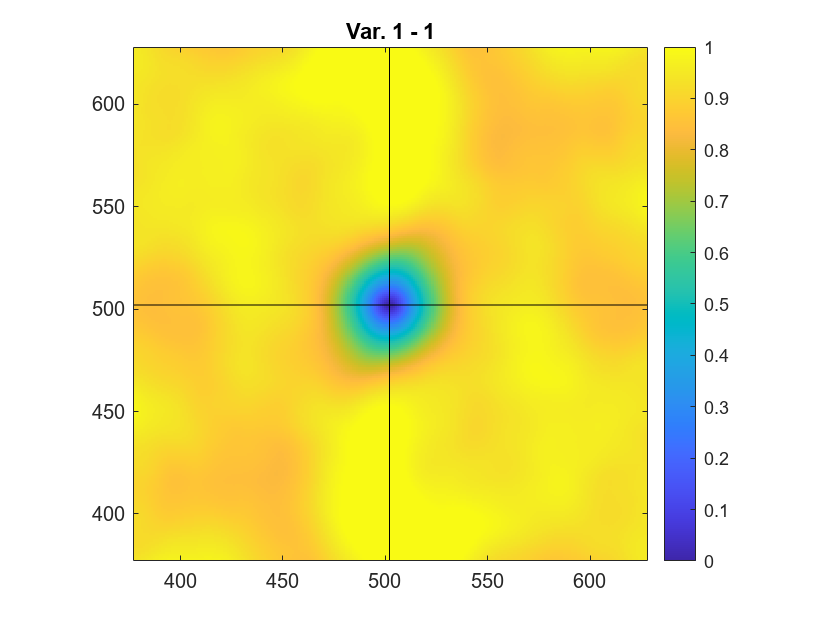

categ = 0; % Specify that the data is not categorical
display = 1; % Set display flag to true for visualization
rank = 0; % Set rank for GeoStatFFT
icode = 1; % Set code for bivariate asymmetry computation

% Adjust values in Z to avoid computational issues:
% Replace zeros with a small value and ones with a value just below one
Z(Z==0)=0.0000001;
Z(Z==1)=0.9999999;
% Compute the variogram using the GeoStatFFT function on the normalized Z values
figure(3000)
[gh, nh] = GeoStatFFT(x0, norminv(Z), icode,categ, display, rank);

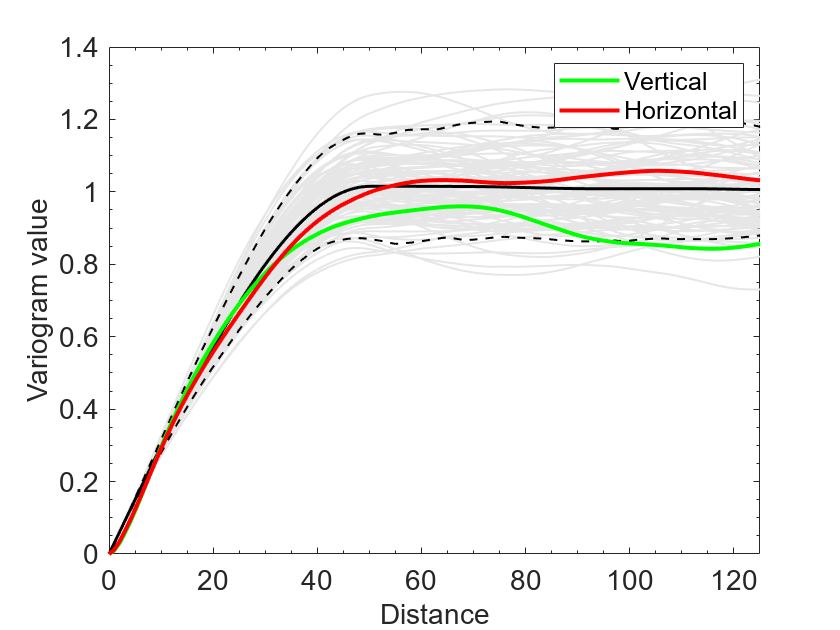

% Simulation of random fields
[z]=fftma([4 50 50 50 0 0 0],1,45124241,100,nx,1,ny,1);
for i =1:100
    gh1{i} = GeoStatFFT(x0, z(:,i), icode);
end

figure(3101)
for i=1:100
    plot(0:length(gh1{i}{1,1}(nx:end,ny))-1, gh1{i}{1,1}(nx:end,ny),'color', [0.9 0.9 0.9], LineWidth=1)
    hold on
    gmean(:,i) = gh1{i}{1,1}(nx:end,ny);
end
plot(0:length(mean(gmean,2))-1,mean(gmean,2), '-k',LineWidth=1.5)
hold on
plot(0:length(quantile(gmean,0.05,2))-1,quantile(gmean,0.05,2),'--k',LineWidth=1)
hold on
plot(0:length(quantile(gmean,0.95,2))-1,quantile(gmean,0.95,2),'--k',LineWidth=1)
hold on
h1 = plot(0:length(gh{1,1}(nx:end,ny))-1,gh{1,1}(nx:end,ny),'-g',LineWidth=2);
hold on
h2 = plot(0:length(gh{1,1}(nx,ny:end))-1,gh{1,1}(nx,ny:end),'-r',LineWidth=2);
legend([h1 h2],{'Vertical', 'Horizontal'})
xlabel('Distance')
ylabel('Variogram value')
fontsize(gca, 14, 'points')
xlim([0 floor(nx/4)])
ylim([0 1.4])
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')